Experiment #1

Move checkerboard across the "main" diagonal and compute metrics at each step.


clear;

fps = 10;
% pause on;

pixels = 5;
rows = 10;
% n = rows * p * 2;
% m = rows * p * 2;
I = checkerboard(pixels, rows);
I_ref = imref2d(size(I));
bg = zeros(size(I) * 2);
bg_ref = imref2d(size(bg));
[I_bg, I_bg_ref] = imfuse(I, I_ref, bg, bg_ref);

step = 1;
len = floor(size(I, 1) / step);
err = struct('x',    cell(1, len), ... 
             'mse',  cell(1, len), ...
             'niqe', cell(1, len), ...
             'piqe', cell(1, len), ...
             'brisque', cell(1, len), ...
             'ssim', cell(1, len));

for x=1:step:size(I)
    T = [1 0 0; 0 1 0; x x 1];
    tform = affine2d(T);
    [J, J_ref] = imwarp(I, I_ref, tform);
    J_bg = imfuse(J, J_ref, bg, bg_ref);
    
    idx = floor(x / step) + 1;
    err(idx).x = x;
    err(idx).mse = log(immse(I_bg, J_bg));
    err(idx).brisque = log(brisque(J_bg));
    err(idx).niqe = log(niqe(J_bg));
    err(idx).piqe = log(piqe(J_bg));
    err(idx).ssim = ssim(I_bg, J_bg);
end

plot([err.x], [err.mse]);
title('')
ylabel('значение метрики')
xlabel('сдвиг')
hold on;
grid on;
plot([err.x], [err.ssim]);
plot([err.x], [err.brisque]);
plot([err.x], [err.niqe]);
plot([err.x], [err.piqe]);
legend('mse (log)', 'ssim', 'brisque (log)', 'niqe (log)', 'piqe');
hold off;

Experiment #2:

- step rows;

- generate rows x rows checkerboard; 

- apply saccadic movement to checkerboard;

- compute quality metrics.

NMIN = 4;
NMAX = 10;
step = 1;
len = NMAX - NMIN + 1;
pixels = 4;

predictableSeed = 1.5;
randomGenerator = rng(predictableSeed);

err = struct('n',       cell(1, len), ... 
             'mse',     cell(1, len), ...
             'niqe',    cell(1, len), ...
             'piqe',    cell(1, len), ...
             'brisque', cell(1, len), ...
             'ssim',    cell(1, len));

for rows = NMIN:step:NMAX
    columns = rows;
    n = rows * pixels * 2;
    m = columns * pixels * 2;
    I = checkerboard(pixels, rows);
    
    saccadeLength = m * n / 2;
    
    saccades = generateSaccades(m * n, saccadeLength);
    origin = originMovement(saccades, saccadeLength);
    D = displacementField2d(origin, m, n, 'yfast');
    warped = imwarp(I, D);

    idx = floor(rows / step) + 1;
    err(idx).n = rows;
    err(idx).mse = log(immse(I, warped));
    err(idx).ssim = ssim(I, warped);

    err(idx).brisque = log(brisque(warped) / brisque(I));
    err(idx).niqe = log(niqe(warped) / niqe(I));
    err(idx).piqe = log(piqe(warped) / piqe(I));

end

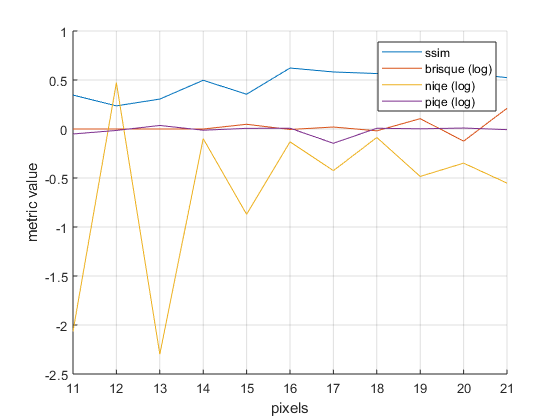


% plot([err.n], [err.mse]);
title('')
ylabel('metric value')
xlabel('rows')
hold on;
grid on;
plot([err.n], [err.ssim]);
plot([err.n], [err.brisque]);
plot([err.n], [err.niqe]*1000);
plot([err.n], [err.piqe]);
legend(...
    'ssim', 'brisque (log)', 'niqe (log)', 'piqe (log)');
hold off;

Experiment #2: 

the same as previous, only step pixels, not rows.

rows = 8;
columns = 10;
PMIN = 10;
PMAX = 20;
step = 1;
len = PMAX - PMIN + 1;

predictableSeed = 1.5;
randomGenerator = rng(predictableSeed);

err = struct('n',       cell(1, len), ... 
             'mse',     cell(1, len), ...
             'niqe',    cell(1, len), ...
             'piqe',    cell(1, len), ...
             'brisque', cell(1, len), ...
             'ssim',    cell(1, len));

for pixels = PMIN:step:PMAX
    n = rows * pixels * 2;
    m = columns * pixels * 2;
    I = checkerboard(pixels, rows, columns);
    
    saccadeLength = m * n / 2;
    
    saccades = generateSaccades(m * n, saccadeLength);
    origin = originMovement(saccades, saccadeLength);
    D = displacementField2d(origin, m, n, 'yfast');
    warped = imwarp(I, D);

    idx = floor(pixels / step) + 1;
    err(idx).n = pixels;
%     err(idx).mse = log(immse(I, warped));
    err(idx).ssim = ssim(I, warped);

    err(idx).brisque = log(brisque(warped) / brisque(I));
    err(idx).niqe = log(niqe(warped) / niqe(I));
    err(idx).piqe = log(piqe(warped) / piqe(I));

end

% plot([err.n], [err.mse]);
title('')
ylabel('metric value')
xlabel('pixels')
hold on;
grid on;
plot([err.n], [err.ssim]);
plot([err.n], [err.brisque]);
plot([err.n], [err.niqe]);
plot([err.n], [err.piqe]);
legend(...
    'ssim', 'brisque (log)', 'niqe (log)', 'piqe (log)');
hold off;